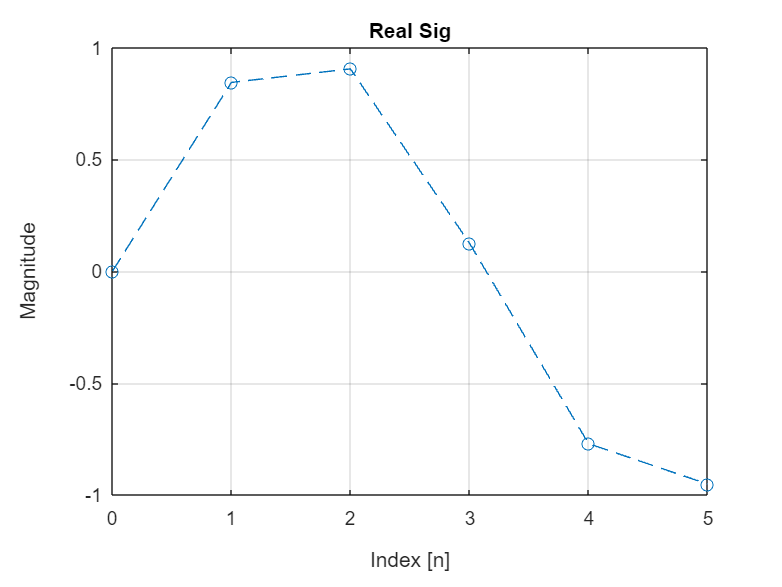

clear all

% Parameters
fs = 100e6; % Sampling frequency - clock domain
f0 = 16e6; % Signal frequency
N = fs/f0; % Number of samples
n = 0:N-1; % Discrete-time index

% Generate samples
sig_re = sin(2*pi*f0*n/fs); % Real part
sig_im = sin(2*pi*f0*n/fs); % Imaginary part

sig_re = [sig_re zeros(1,100)]
figure;
plot(n,sig_re,'--o');
title('Real Sig');
xlabel('Index [n]');
ylabel('Magnitude');
grid on;

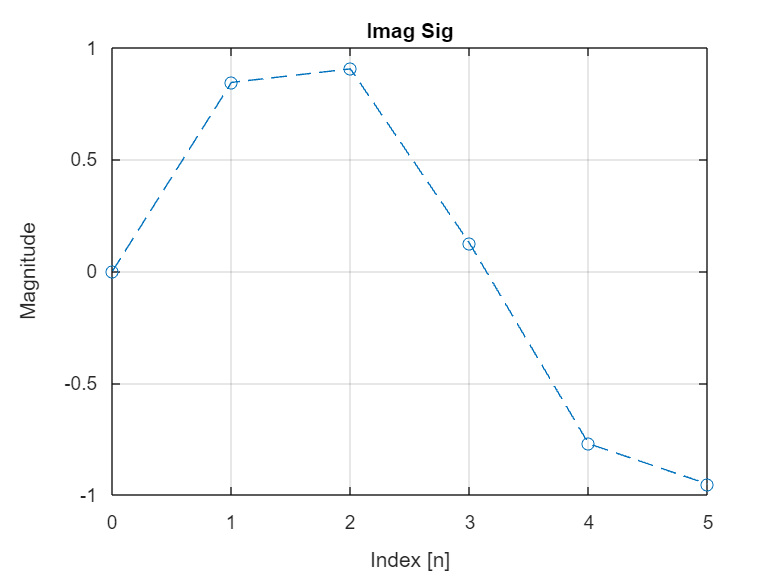

figure
plot(n,sig_im,'--o');
title('Imag Sig');
xlabel('Index [n]');
ylabel('Magnitude');
grid on;

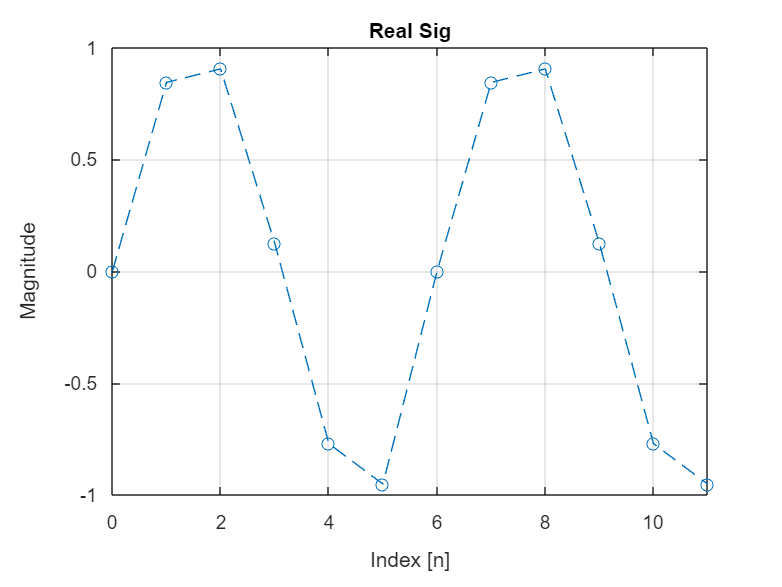


figure;
plot([n, n+6],[sig_re, sig_re],'--o');
title('Real Sig');
xlabel('Index [n]');
ylabel('Magnitude');
grid on;

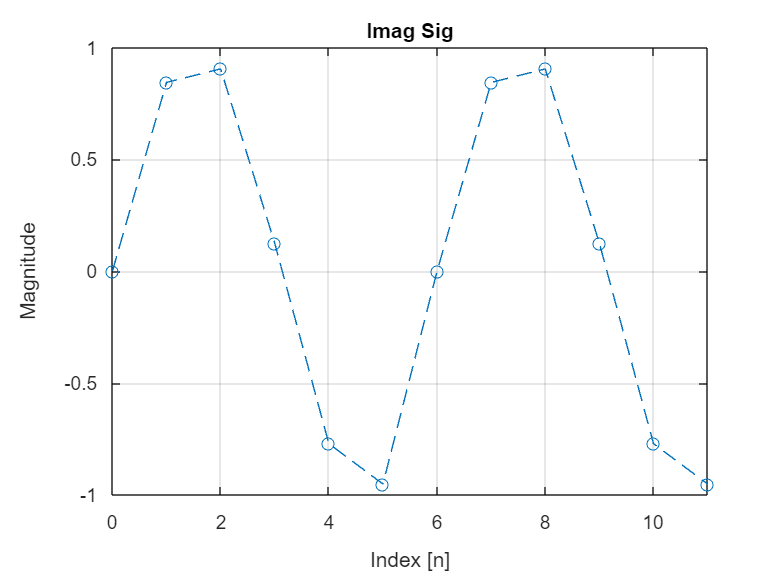

figure
plot([n, n+6],[sig_im, sig_im],'--o');
title('Imag Sig');
xlabel('Index [n]');
ylabel('Magnitude');
grid on;


SIG_RE = fft(sig_re,)